===============================================================================

# Pràctica 8. Derivación Numérica

Table of Contents

[1. Introducció ](about:blank<#H_F4BF7159%3E)    [MATLAB®  -  Derivació numèrica ](about:blank<#H_CBE97692%3E)    [MATLAB®  - Vector gradient ](about:blank<#H_4F7B8C83%3E)[2. Aprenem... Fòrmules bàsiques. ](about:blank<#H_C19E72DB%3E)    [Exercici 1.  ](about:blank<#H_FFE5EB9F%3E)    [Exercici 2  ](about:blank<#H_41100B9A%3E)    [Exercici 3 ](about:blank<#H_A25500A8%3E)    [Exercici 4 ](about:blank<#H_03F4653E%3E)[3. Practiquem...   ](about:blank<#H_B40B51D5%3E)    [Exercici 5  O(h) ](about:blank<#H_37CAB3F2%3E)    [Exercici 6  O(h^2) ](about:blank<#H_4C1C9DBD%3E)[4. Practiquem...   ](about:blank<#H_D9715494%3E)    [Exercici 7   O(h^2) ](about:blank<#H_DFDCC61D%3E)[5. AutoAvaluació  ](about:blank<#H_A7FDA8EE%3E)    [Exercici 8 ](about:blank<#H_3A8A242E%3E)    [Exercici 9.  O(h)](about:blank<#H_A4A4F4EB%3E)

## 1. Introducció

A més a més dels exercicis d'aquest script teniu disponibles exercicis en el document Guia-Lab8.pdf i en el document CN_full7.pdf, els podeu trobar en el campus virtual. **MATLAB®  -  Derivació numèrica**

Use the `diff` function to approximate partial derivatives with the syntax `Y = diff(f)/h`, where `f` is a vector of function values evaluated over some domain, `X`, and `h` is an appropriate step size.

For example, the first derivative of `sin(x)` with respect to `x` is `cos(x)`, and the second derivative with respect to `x` is `-sin(x)`. You can use `diff` to approximate these derivatives.

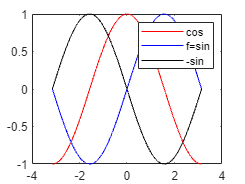

In this plot the blue line corresponds to the original function, `sin`. The red line corresponds to the calculated first derivative, `cos`, and the black line corresponds to the calculated second derivative, `-sin`.

*Copyright 2015 The MathWorks, Inc.*

**MATLAB®  - Vector gradient**

Calculate the 2-D gradient of $x e^{-x^2-y^2}$ on a grid.

Plot the contour lines and vectors in the same figure.

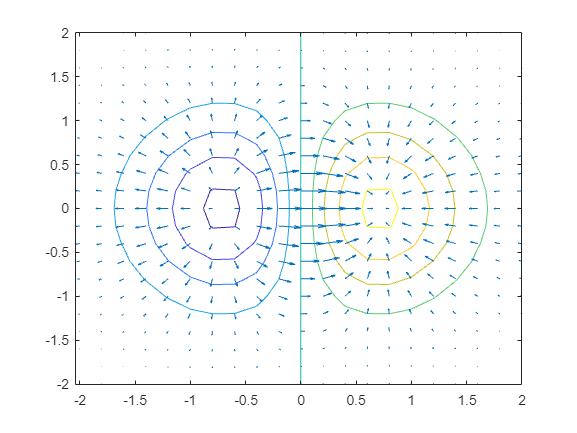

*Copyright 2012 The MathWorks, Inc.*

## 2. Aprenem... Fòrmules bàsiques.

Exercici 1. 

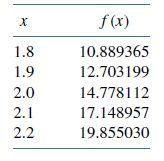

Calcular f'(2.0) con h=0.1 y h=0.2. Los datos son de f(x)=x*e^x, calcular los errores absolutos. Crear tabla para visualitzar error absoluto en las fórmulas usadas

x = linspace(1.8, 2.2, 5)

x =     1.8000    1.9000    2.0000    2.1000    2.2000


y = [10.889365 12.703199 14.778112 17.138957 19.855030]

y =    10.8894   12.7032   14.7781   17.1390   19.8550


h = 0.2

h = 0.2000

syms a

'syms' requires Symbolic Math Toolbox.

f = a*exp(1)^a
fp = diff(f)
listh = [0.2 0.1]
listfp = [fp(2) fp(2)]
enrere = (y(5)-y(3))/h
h = 0.1
enrere2 = (y(4) - y(3))/h
listaprox = [enrere enrere2]
listerr = [abs(enrere, fp(2)) abs(enrere2, fp(2))]
listrel = [listerr(1)/fp(2) listerr(2)/fp(2)]
R = [listh;listfp;listaprox;listerr;listrel]';
T = array2table(R, 'VariableNames', {'h', 'derivada', 'aprox', 'errabs', 'errrel' });
disp(T)